Cargamos el dataset `datos_huracanes` dentro de la carpeta datasets.

data = load('datasets\datos_huracanes.mat');
P = data.P; % Patrones de entrada
T = data.T; % Salidas deseadas

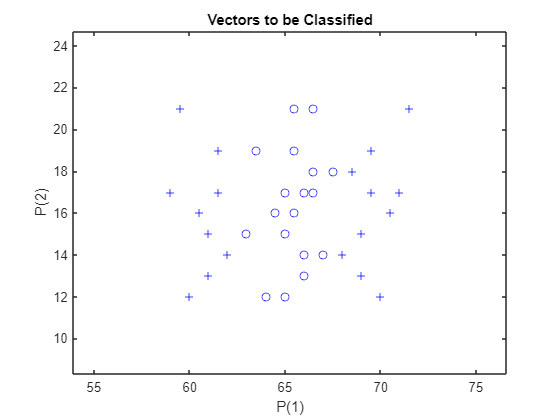

% Creación del perceptón simple
red = newp(minmax(P),1);

% Entrenamiento de la red
red = train(red, P, T);

% Obtenemos las salidas para los patrones de entrenamiento
S = sim(red, P);

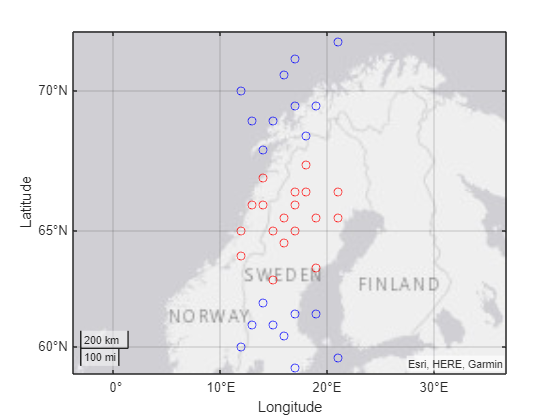

% Ploteamos las latitudes y longitudes con geoscatter

count_0 = 1;
count_1 = 1;

for i=1:37
    if T(i)==0
        lat_0(count_0) = P(1,i);
        lon_0(count_0) = P(2,i);
        count_0 = count_0 + 1;
    else
        lat_1(count_1) = P(1,i);
        lon_1(count_1) = P(2,i);
        count_1 = count_1 + 1;
    end
end

figure()
geoscatter(lat_0, lon_0, 'ro'); 
hold on;
geoscatter(lat_1, lon_1, 'bo');

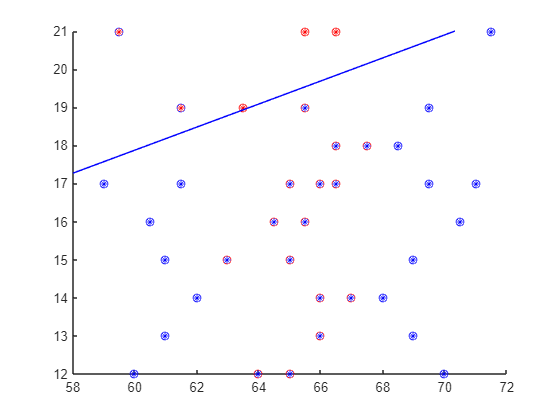

% Ploteamos latitudes y longitudes reales frente a la salida de la red

count_0 = 1;
count_1 = 1;

for i=1:37
    if S(i)==0
        Slat_0(count_0) = P(1,i);
        Slon_0(count_0) = P(2,i);
        count_0 = count_0 + 1;
    else
        Slat_1(count_1) = P(1,i);
        Slon_1(count_1) = P(2,i);
        count_1 = count_1 + 1;
    end
end

figure()
scatter(lat_0, lon_0, 'ro'); 
hold on;
scatter(lat_1, lon_1, 'bo');
scatter(Slat_0, Slon_0, 'r*'); 
scatter(Slat_1, Slon_1, 'b*');
plotpc(red.IW{1}, red.b{1});